# Fixed-Interval Smoothing for `trackingEKF`

Create a truth trajectory based on a constant turn motion model and generate 2-D position measurements.

rng(2020); % For repeatable results
% Initialization
dt = 1;
simTime = 50;
tspan = 0:dt:simTime;
trueInitialState = [0; 1; 0; 1; 5]; % [x;vx;y;vy;omega]
processNoise = diag([0.5; 0.5; 0.1]); % process noise matrix
measureNoise = diag([4 4 1]); % measurement noise matrix

numSteps = length(tspan);
trueStates = NaN(5,numSteps);
trueStates(:,1) = trueInitialState;


% Propagate the constant turn model and generate the measurements with
% noise. 
for i = 2:length(tspan)
    trueStates(:,i) = constturn(trueStates(:,i-1),chol(processNoise)*randn(3,1),dt);    
end
measurements = ctmeas(trueStates) + chol(measureNoise)*randn(3,numSteps);


Plot the truth trajectory and the measurements.

figure
plot(trueStates(1,1),trueStates(3,1),'r*','HandleVisibility','off')
hold on
plot(trueStates(1,:),trueStates(3,:),'r','DisplayName','Truth')
plot(measurements(1,:),measurements(2,:),'ko','DisplayName','Measurements')
xlabel('x (m)')
ylabel('y (m)')
axis image

Create a `trackingEKF` filter object based on the constant turn motion model. 

initialGuess = [measurements(1,1);- 1; measurements(2,1); -1; 0];
filter = trackingEKF(@constturn,@ctmeas,initialGuess, ...
    'StateCovariance', diag([1,1,1,1,10]), ...
    'StateTransitionJacobianFcn',@constturnjac, ...
    'MeasurementNoise',measureNoise, ...
    'MeasurementJacobianFcn',@ctmeasjac, ...
    'EnableSmoothing',true, ...
    'MaxNumSmoothingSteps',numSteps);

estimateStates = NaN(size(trueStates));
estimateStates(:,1) = filter.State;

Propagate the filter and update the estimated state with the measurements.

for i=2:length(tspan)
    predict(filter,dt)
    estimateStates(:,i) = correct(filter,measurements(:,i));
end

Visualize the estimated results.

plot(estimateStates(1,:),estimateStates(3,:),'b','DisplayName','Forward filtering')

Backward smooth the estimated states.

smoothStates = smooth(filter);

Visualize the smoothed trajectory.

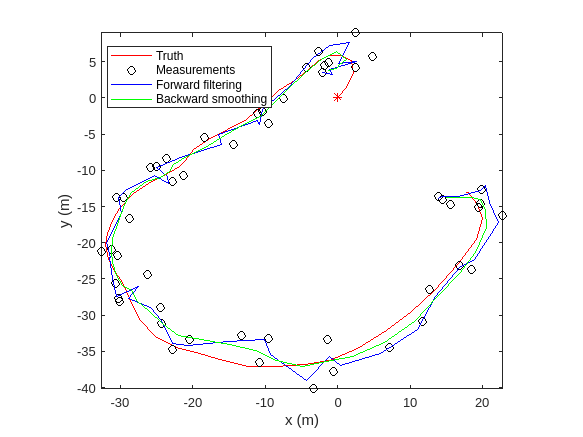

plot(smoothStates(1,:),smoothStates(3,:),'g','DisplayName','Backward smoothing')
legend('Location','best')

Obtain the estimation errors. 

forwardError = abs(estimateStates - trueStates);
smoothError = abs(smoothStates - trueStates(:,1:end-1));
rmsForward = sqrt(mean(forwardError'.^2))

rmsForward =     1.6492    1.2326    1.6138    1.1619    5.0195


rmsSmooth = sqrt(mean(smoothError'.^2))

rmsSmooth =     0.9201    0.6587    1.2122    0.6139    2.2426


Visualize the estimation errors. From the results, the smoothing process reduces the estimation errors.

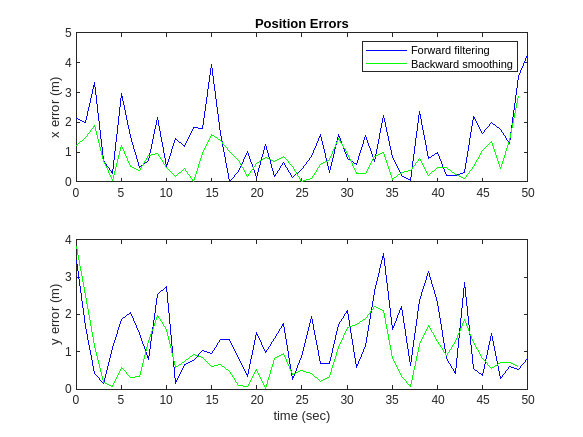

figure
subplot(2,1,1)
plot(tspan,forwardError(1,:),'b')
hold on;
plot(tspan(1:end-1),smoothError(1,:),'g')
title('Position Errors')
legend('Forward filtering','Backward smoothing')
ylabel('x error (m)')
subplot(2,1,2)
plot(tspan,forwardError(3,:),'b')
hold on
plot(tspan(1:end-1),smoothError(3,:),'g')
xlabel('time (sec)')
ylabel('y error (m)')

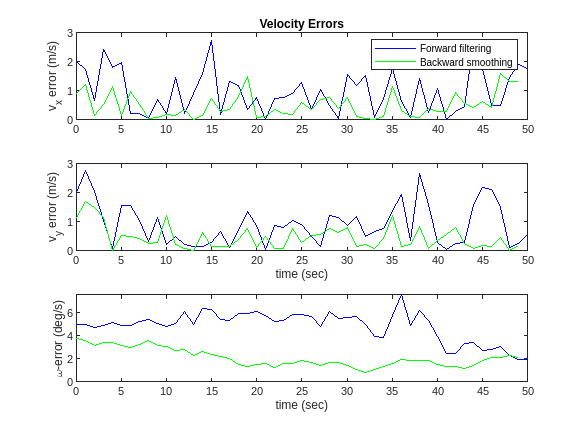


figure
subplot(3,1,1)
plot(tspan,forwardError(2,:),'b')
hold on;
plot(tspan(1:end-1),smoothError(2,:),'g')
title('Velocity Errors')
legend('Forward filtering','Backward smoothing')
ylabel('v_x error (m/s)')
subplot(3,1,2)
plot(tspan,forwardError(4,:),'b')
hold on;
plot(tspan(1:end-1),smoothError(4,:),'g')
xlabel('time (sec)')
ylabel('v_y error (m/s)')
subplot(3,1,3)
plot(tspan,forwardError(5,:),'b')
hold on;
plot(tspan(1:end-1),smoothError(5,:),'g')
xlabel('time (sec)')
ylabel('\omega-error (deg/s)')

*Copyright 2020 The MathWorks, Inc.*